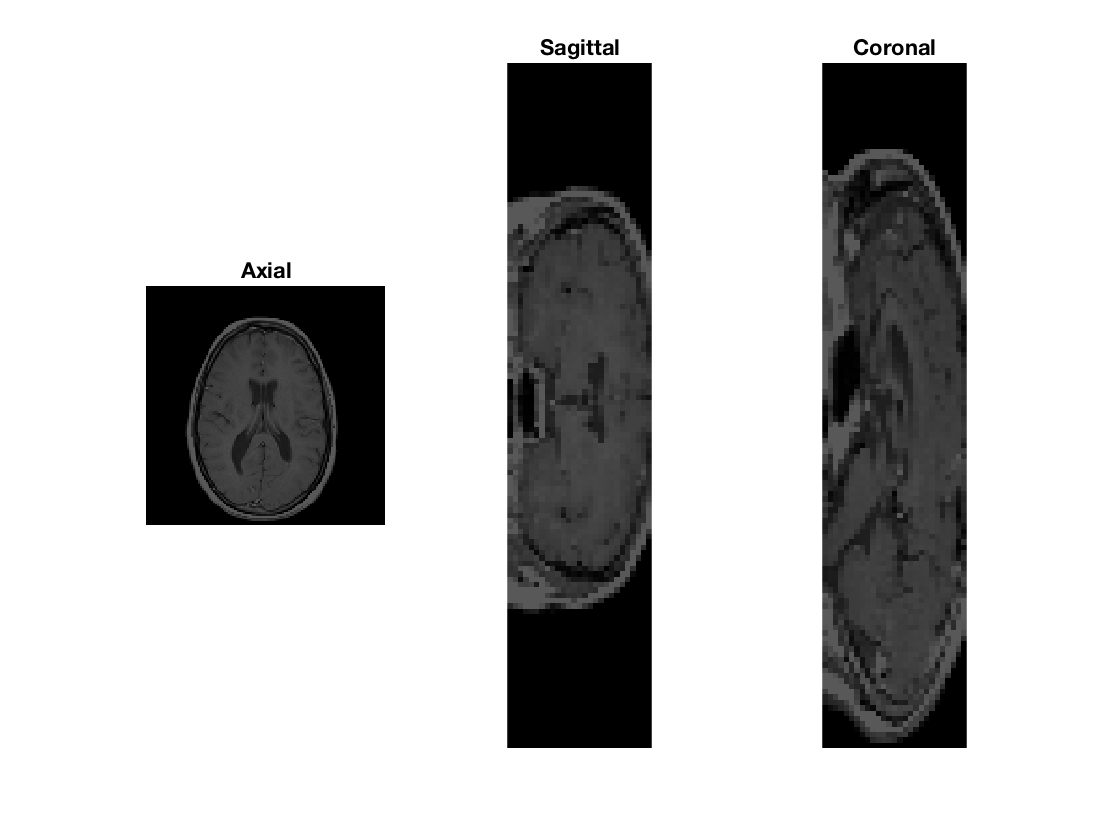

% Load the MRI image from matlab.
load mri
% Suppress the gray scale value 1, Reduce the dimension from 4 --> 3
data = squeeze(D);

% Plot the axial, sagittal and coronal view of the MRI image.
% Axial view at slice 16.
figure(1)
subplot(1,3,1)
axial = squeeze(data(:,:,16));
imshow(axial), title('Axial');

% Sagittal view at slice 64.
subplot(1,3,2)
sagittal = squeeze(data(64,:,:));
imshow(sagittal), title('Sagittal');

% Coronal view at slice 64.
subplot(1,3,3)
coronal = squeeze(data(:,64,:));
imshow(coronal), title('Coronal');

**Section II: **

**Prewitt and Sobel Edge filters**

% In this task
% We just work on the data in the axial view at slice 16 for edge detection. 

% Gradients along x and y axis: Using prewitt kernal
[Grad_x_prewitt, Grad_y_prewitt] = imgradientxy(axial,'prewitt');

% Gradients along x and y axis: Using sobel kernal
[Grad_x_sobel, Grad_y_sobel] = imgradientxy(axial,'sobel');

% Magnitude and direction of gradients: using prewitt kernal
[Gmag_prewitt, Gdir_prewitt] = imgradient(axial,'prewitt');

% Magnitude and direction of gradients: using sobel kernal
[Gmag_sobel, Gdir_sobel] = imgradient(axial,'sobel');

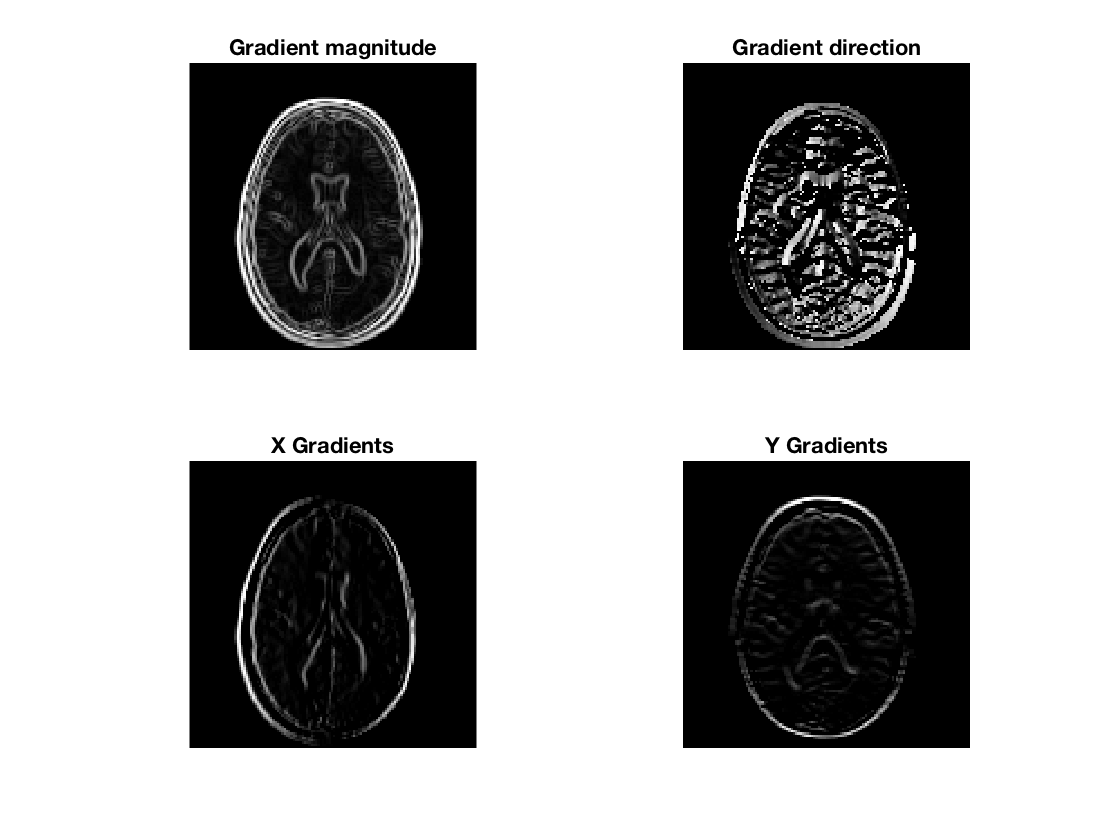

% For Prewitt kernel:
figure(3)
subplot(2,2,1)
imshow(uint8(Gmag_prewitt), []), title('Gradient magnitude')
subplot(2,2,2)
imshow(uint8(Gdir_prewitt), []), title('Gradient direction')
subplot(2,2,3)
imshow(uint8(Grad_x_prewitt), []), title('X Gradients')
subplot(2,2,4)
imshow(uint8(Grad_y_prewitt), []), title('Y Gradients')

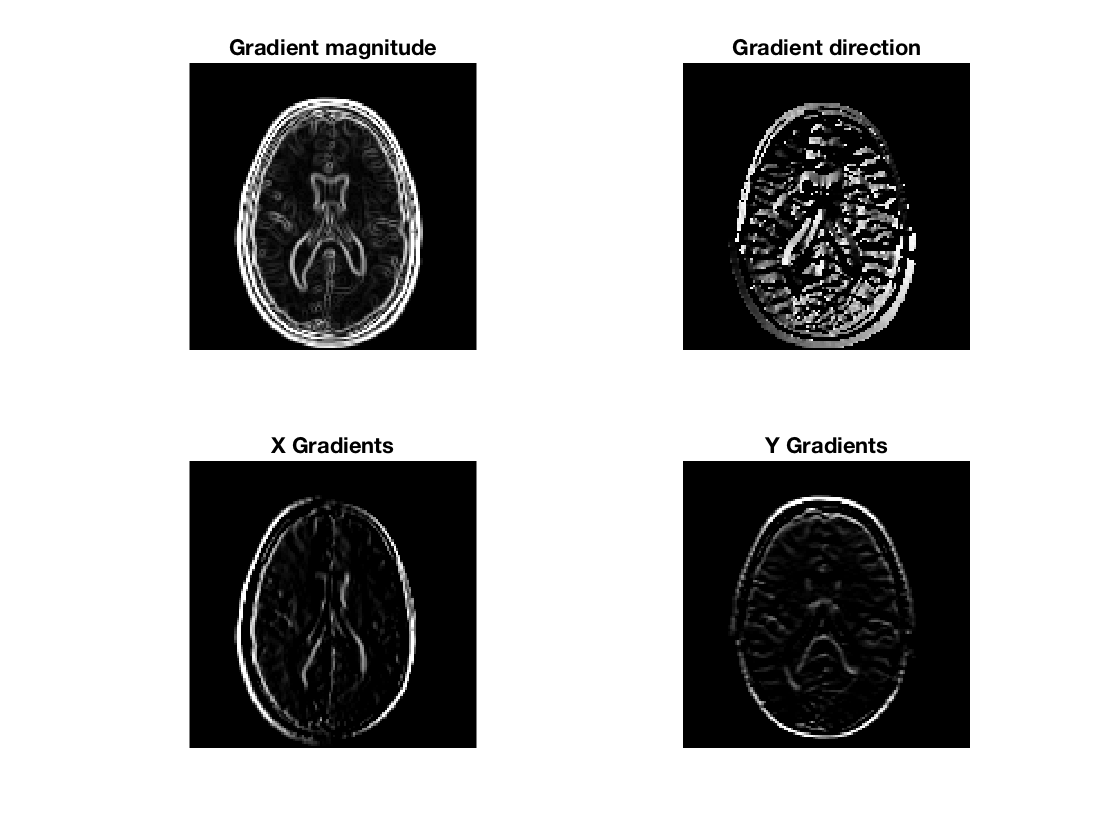

% For Sobel kernel:
figure(4)
subplot(2,2,1)
imshow(uint8(Gmag_sobel), []), title('Gradient magnitude')
subplot(2,2,2)
imshow(uint8(Gdir_sobel), []), title('Gradient direction')
subplot(2,2,3)
imshow(uint8(Grad_x_sobel), []), title('X Gradients')
subplot(2,2,4)
imshow(uint8(Grad_y_sobel), []), title('Y Gradients')

**Canny edge detection **

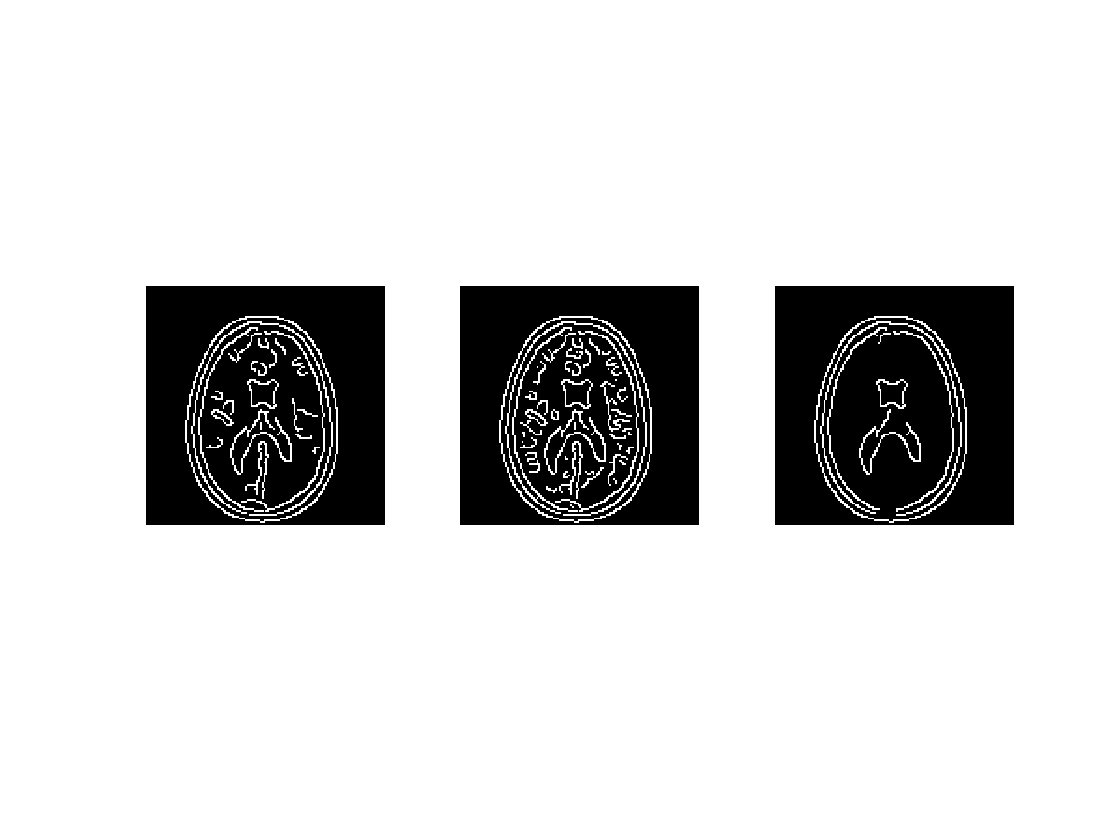

figure(5)
% Using default threshold value:
canny_0 = edge(axial, 'canny');

% Using threshold value for 0.05 in prewitt kernal.
canny_1 = edge(axial, 'canny', 0.05);

% Using threshold value for 0.3 in prewitt kernal.
canny_2 = edge(axial, 'canny', 0.3);

subplot(1,3,1)
imshow(canny_0), title = 'default threshold';
subplot(1,3,2)
imshow(canny_1), title = '0.05 threshold';
subplot(1,3,3)
imshow(canny_2), title = '0.3 threshold';


% 
[BW0,thresh0] = edge(axial,'canny');
% BW_0 = edge(axial,'canny',thresh0);
% 
[BW1,thresh1] = edge(axial,'canny',0.3);
% BW_1 = edge(axial,'canny',thresh1);
% 
[BW2,thresh2] = edge(axial,'canny',0.05);
% BW_2 = edge(axial,'canny',thresh2);
% figure (4)


**III. Kmeans clustering **

help kmeans

 kmeans K-means clustering.
    IDX = kmeans(X, K) partitions the points in the N-by-P data matrix X
    into K clusters.  This partition minimizes the sum, over all clusters, of
    the within-cluster sums of point-to-cluster-centroid distances.  Rows of X
    correspond to points, columns correspond to variables.  Note: when X is a
    vector, kmeans treats it as an N-by-1 data matrix, regardless of its
    orientation.  kmeans returns an N-by-1 vector IDX containing the cluster
    indices of each point.  By default, kmeans uses squared Euclidean
    distances.
 
    kmeans treats NaNs as missing data, and ignores any rows of X that
    contain NaNs.
 
    [IDX, C] = kmeans(X, K) returns the K cluster centroid locations in
    the K-by-P matrix C.
 
    [IDX, C, SUMD] = kmeans(X, K) returns the within-cluster sums of
    point-to-centroid distances 

%% Kmeans clustering 
% process of kmeans clustering 
%   region splittng - start with one big region, seperate regions that are
%   not sufficiently homogeneous 
vector = reshape(axial,numel(axial),1);
[IDX_4,C_4,SUM_4] = kmeans(single(vector),4,'Display','final');

Replicate 1, 8 iterations, total sum of distances = 370670.
Best total sum of distances = 370688


[IDX_8,C_8, SUM_8] = kmeans(single(vector),8,'Display','final');

Replicate 1, 9 iterations, total sum of distances = 51849.5.
Best total sum of distances = 51849.4


[IDX_20,C_20, SUM_20] = kmeans(single(vector),20,'Display','final');

Replicate 1, 3 iterations, total sum of distances = 7640.97.
Best total sum of distances = 7641.13


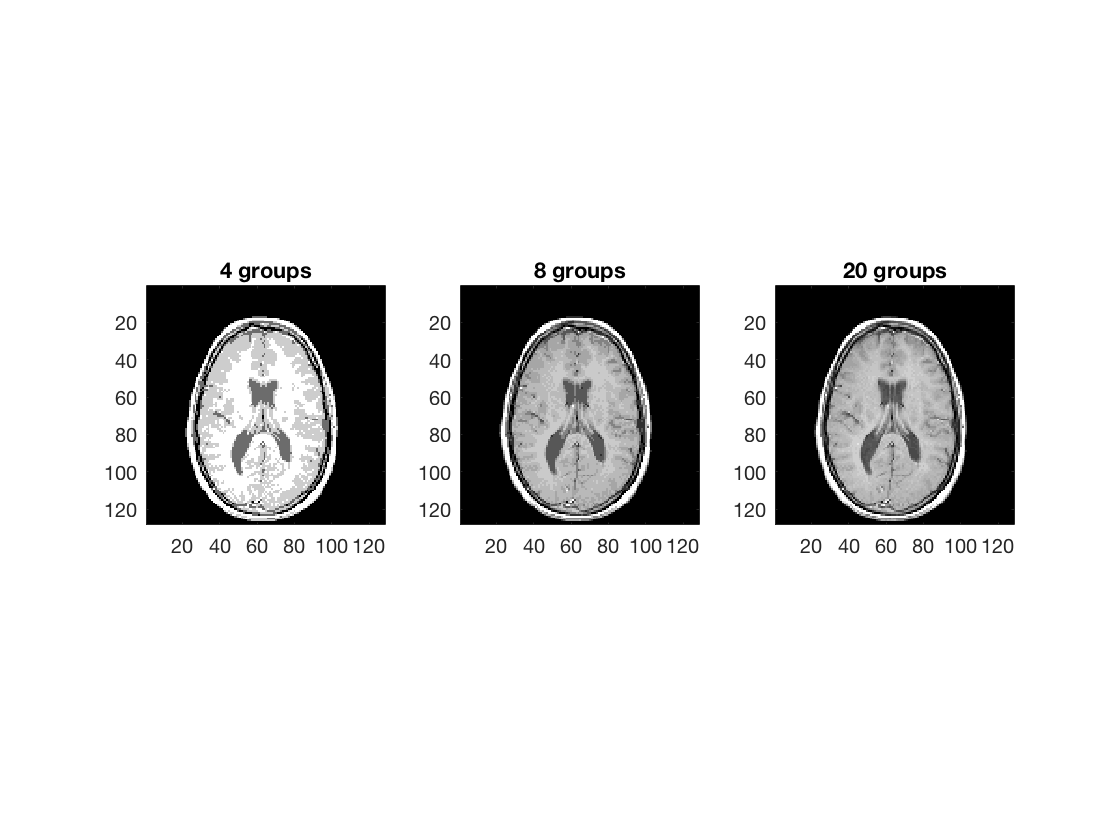


vector_4 = zeros(size(vector));
vector_8 = zeros(size(vector));
vector_20 = zeros(size(vector));

for j = 1:length(C_4)
    for i = 1:length(IDX_4)
        if(IDX_4(i) == j)
            vector_4(i) = C_4(j);  
        end
    end 
end

for j = 1:length(C_8)
    for i = 1:length(IDX_8)
        if(IDX_8(i) == j)
               vector_8(i) = C_8(j);
        end
    end 
end

for j = 1:length(C_20)
    for i = 1:length(IDX_20)
        if(IDX_20(i) == j)
               vector_20(i) = C_20(j);
        end
    end 
end

axial_group4 = reshape(vector_4,size(axial));
axial_group8 = reshape(vector_8,size(axial));
axial_group20 = reshape(vector_20,size(axial));

figure(5)
subplot(1,3,1)
imagesc(axial_group4);
axis('square')
title('4 groups')
subplot(1,3,2)
imagesc(axial_group8);
axis('square')
title('8 groups')
subplot(1,3,3)
imagesc(axial_group20);
axis('square')
title('20 groups')

vector = reshape(axial,numel(axial),1);
[IDX_4,C_4,SUM_4] = kmeans(single(vector),4,'Display','iter');

  iter	 phase	     num	         sum
     1	     1	   16384	      402680
     2	     1	     680	      377324
     3	     1	     370	      370065
     4	     1	     497	      360682
     5	     1	     339	      353645
     6	     1	     375	      345197
     7	     1	     300	      338624
     8	     1	     352	      328301
     9	     1	     280	      317782
    10	     1	     219	      306544
    11	     1	     209	      291698
    12	     1	     128	      286381
    13	     1	      13	      286252
Best total sum of distances = 286254


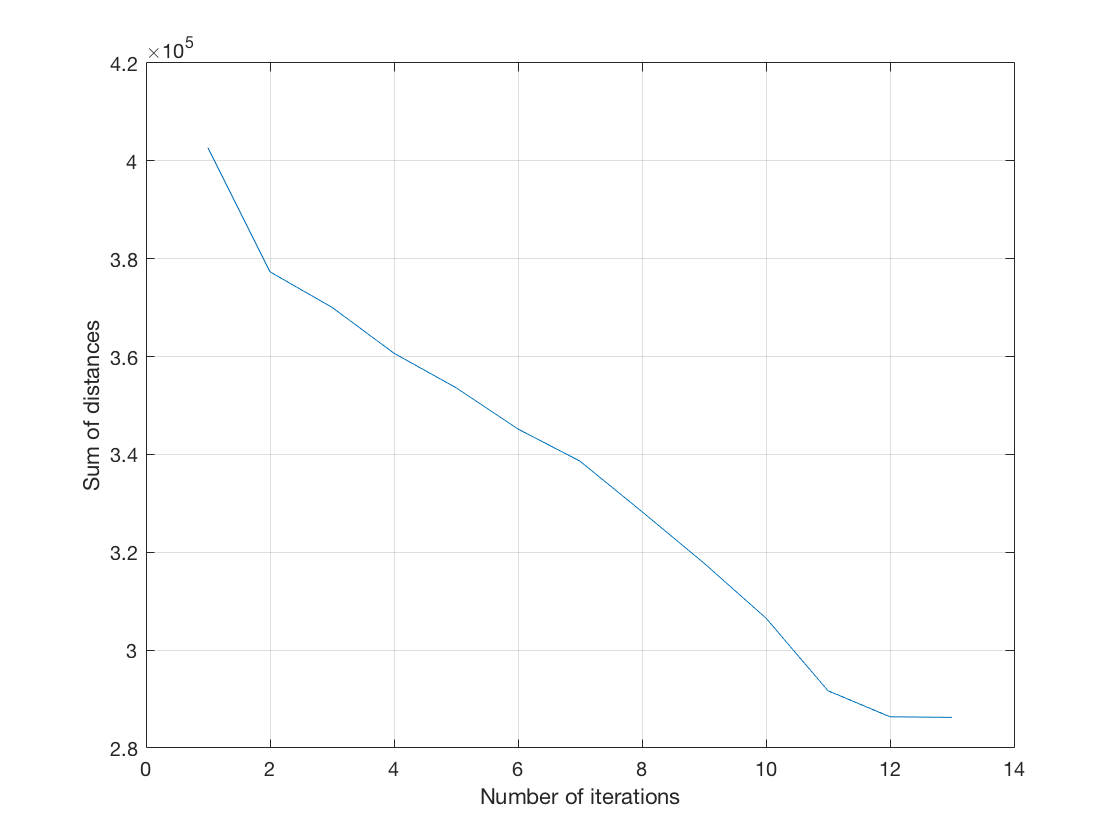

figure(7)
% plot for 4 clusters
iter_4 = 1:1:13;
Sum_4 = [402680,377324,370065,360682,353645,345197,338624,328301,317782,306544,291698,286381,286252];
plot(iter_4,Sum_4)
axis('on')
ylabel('Sum of distances','fontweight','bold') 
xlabel('Number of iterations','fontweight','bold')
grid on